4)

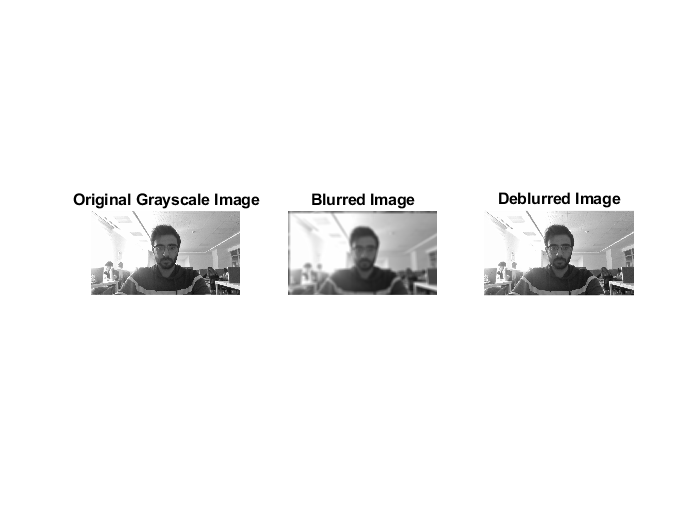

tic;
subplot(1,3,1);
ahmet=imread('C:\Users\ahmet\Desktop\4.sınıf\image\mp4\ahmet.jpg');
ahmet_gray=rgb2gray(ahmet);
yoldas=im2double(ahmet_gray); 
imshow(yoldas);
title('Original Grayscale Image','fontsize', [12]);
 
subplot(1,3,2);
[x,y]=size(yoldas);
fft_ahmet=fft2(yoldas,x,y);

n=2*round(y/100)+1;    
m = ones(n); 
mask = m/sum(m(:));
mask_FFT=fft2(mask,x,y);
Blur_FFT_Image=fft_ahmet.*mask_FFT;
Blur_Image=ifft2(Blur_FFT_Image);
imshow(Blur_Image);
title('Blurred Image','fontsize', [12]);
 
subplot(1,3,3);
Deblurred=Blur_FFT_Image./mask_FFT;
Deblurred_ifft=ifft2(Deblurred);
imshow(real(Deblurred_ifft));
title('Deblurred Image','fontsize', [12]);

 
toc;

Elapsed time is 0.555646 seconds.
